# CSC 6740 Data Mining: Assignment 3

# The Pagerank Algorithm

                                                      
$$rank(page_i) = c \sum_{page_j \; \in \; I_{page_i}} \frac{rank(page_j)}{| O_{page_j} |} + \frac{(1-c)}{n}$$


## NAME: Jesse Annan

## ID: 002708111

close all; clear; clc;

                                        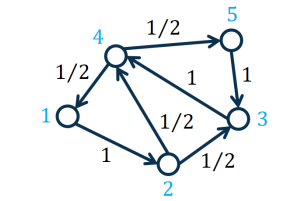

transpMatrix =  [0 0 0 1/2 0; 1 0 0 0 0; 0 1/2 0 0 1; 0 1/2 1 0 0; 0 0 0 1/2 0]; % P transpose
pRank = pageRank(transpMatrix)

pRank =     0.1556
    0.1622
    0.2312
    0.2955
    0.1556


function pRank = pageRank(transpMatrix)
    %{
        pagerank - this function takes the transition probability matrix of
        a graph and with a decay factor, c = 0.85, generates the pagerank
        for each node (in the graph).
    %}

    n = length(transpMatrix); decayFactor = .85; iterVal = 30;
    transpMatrix = decayFactor * transpMatrix;
    transpMatrix = transpMatrix + ( zeros(n) + (1 - decayFactor)/n );
    
    pRank = []; % pagerank array after k iterations
    k = 1; pRank(:,k) = 1/n * ones(n,1); % initial page rank (k=1) for each page_i

    while k <= iterVal
        pRank(:,k+1) = transpMatrix * pRank(:,k);
        k = k + 1;
    end
    
    pRank = pRank(:,end);
end




% function [pRank, iterVal] = pageRank2(transMatrix, tol)
%     %{
%         pagerank - this function takes the transition probability matrix of
%         a graph and with a decay factor, c = 0.85, generates the pagerank
%         for each node (in the graph).
%     %}
% 
%     n = length(transMatrix); iterVal = 1; decayFactor = .85;
%     pRank = [] ; % pagerank array after k iterations
% 
%     pRank(:,iterVal) = 1/n * ones(n,1); % initial page rank for each page_i
%     transMatrix = decayFactor * transMatrix;
%     transMatrix = transMatrix + ( zeros(n) + (1 - decayFactor)/n );
%     pRank(:,iterVal+1) = transMatrix * pRank(:,iterVal);
% 
%     while norm( pRank(:,iterVal+1) - pRank(:,iterVal) ) > tol
%         pRank(:,iterVal+2) = transMatrix * pRank(:,iterVal+1);
%         iterVal = iterVal + 1;
%     end
%     
%     pRank = pRank(:,end); iterVal = iterVal + 1;
% end